# HomeTask 5

GitHub source Code:         https://github.com/zizowasfy/Dynamic-Model-of-a-RP-Robot.git

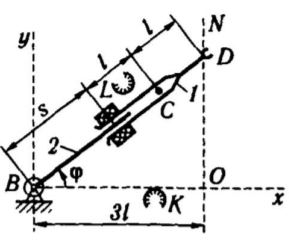

clear all
close all
% Defining the variables
syms phi S dphi dS ddphi ddS L d1 d2 m1 m2 I1 I2 g real

## Forward Kinematics


$$T_{H\;} =R_z \left(\phi \right)\cdot T_x \left(S\right)\cdot T_x \left(L\right)\cdot T_x \left(L\right)$$


T_H = RotR("z",phi) * Trans("x",S) * Trans("x",L) * Trans("x",L)

$$T\_H = \left(\begin{array}{cccc} \cos\left(\phi \right) & -\sin\left(\phi \right) & 0 & 2\,L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\\ \sin\left(\phi \right) & \cos\left(\phi \right) & 0 & 2\,L\,\sin\left(\phi \right)+S\,\sin\left(\phi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T00 = eye(4)

T00 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T01 = RotR("z",phi) * Trans("x",S)

$$T01 = \left(\begin{array}{cccc} \cos\left(\phi \right) & -\sin\left(\phi \right) & 0 & S\,\cos\left(\phi \right)\\ \sin\left(\phi \right) & \cos\left(\phi \right) & 0 & S\,\sin\left(\phi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02 = RotR("z",phi) * Trans("x",S) * Trans("x",L)   % From Origin to C

$$T02 = \left(\begin{array}{cccc} \cos\left(\phi \right) & -\sin\left(\phi \right) & 0 & L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\\ \sin\left(\phi \right) & \cos\left(\phi \right) & 0 & L\,\sin\left(\phi \right)+S\,\sin\left(\phi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = RotR("z",phi) * Trans("x",S) * Trans("x",L) * Trans("x",L)

$$T03 = \left(\begin{array}{cccc} \cos\left(\phi \right) & -\sin\left(\phi \right) & 0 & 2\,L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\\ \sin\left(\phi \right) & \cos\left(\phi \right) & 0 & 2\,L\,\sin\left(\phi \right)+S\,\sin\left(\phi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Origin Point and the center point masses of the links
O0 = [0 0 0]'

O0 =      0
     0
     0


O1 = [0 0 0]'

O1 =      0
     0
     0


O2 = [T02(1,4) T02(2,4) T02(3,4)]'

$$O2 = \left(\begin{array}{c} L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\\ L\,\sin\left(\phi \right)+S\,\sin\left(\phi \right)\\ 0 \end{array}\right)$$


% Axis of Action ( Rotation / Translation ) at each center point
Z0 = T00(1:3,3)        % Rotation about z-axis -> 3rd column in the Rotation matrix of T00

Z0 =      0
     0
     1


Z1 = T02(1:3,1)        % Translation along x-axis -> 1st column in the Rotation matrix of T02

$$Z1 = \left(\begin{array}{c} \cos\left(\phi \right)\\ \sin\left(\phi \right)\\ 0 \end{array}\right)$$


% Linear Velocity Jacobian of each Link
Zer = [0 0 0]';
Jv1 = [cross(Z0,(O1-O0)), Zer]

Jv1 =      0     0
     0     0
     0     0


Jv2 = [cross(Z0,(O2-O0)), Z1]

$$Jv2 = \left(\begin{array}{cc} -L\,\sin\left(\phi \right)-S\,\sin\left(\phi \right) & \cos\left(\phi \right)\\ L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right) & \sin\left(\phi \right)\\ 0 & 0 \end{array}\right)$$


% Angular Velocity Jacobian of each Link
Zer = [0 0 0]'

Zer =      0
     0
     0


Jw1 = [Z0, Zer]

Jw1 =      0     0
     0     0
     1     0


Jw2 = [Z0, Zer]

Jw2 =      0     0
     0     0
     1     0



% Kinetic Energy of each Link
R1 = T00(1:3,1:3);
R2 = T02(1:3,1:3);

q = [phi;S];
D1 = m1*Jv1'*Jv1 + Jw1'*R1*I1*R1'*Jw1    

$$D1 = \left(\begin{array}{cc} I_{1} & 0\\ 0 & 0 \end{array}\right)$$

D2 = m2*Jv2'*Jv2 + Jw2'*R2*I2*R2'*Jw2

$$D2 = \begin{array}{l} \left(\begin{array}{cc} I_{2}+m_{2}\,{\left(L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\right)}^{2}+m_{2}\,{\left(L\,\sin\left(\phi \right)+S\,\sin\left(\phi \right)\right)}^{2} & \sigma_{1}\\ \sigma_{1} & m_{2}\,{\cos\left(\phi \right)}^{2}+m_{2}\,{\sin\left(\phi \right)}^{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,\sin\left(\phi \right)\,\left(L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\right)-m_{2}\,\cos\left(\phi \right)\,\left(L\,\sin\left(\phi \right)+S\,\sin\left(\phi \right)\right) \end{array}$$

D=D1+D2;
D=simplify(D)

$$D = \left(\begin{array}{cc} m_{2}\,L^{2}+2\,m_{2}\,L\,S+m_{2}\,S^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$


% Potential Energy of each Link
P1 = m1 * g * O1(2);
P2 = m2 * g * O2(2);
P = P1+P2;
G1 = diff(P, q(1))

$$G1 = g\,m_{2}\,\left(L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\right)$$

G2 = diff(P, q(2))

$$G2 = g\,m_{2}\,\sin\left(\phi \right)$$

G = [G1 ; G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\left(L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\right)\\ g\,m_{2}\,\sin\left(\phi \right) \end{array}\right)$$


% Calculating the Centrifugal and Coriolis effect
dq = [dphi; dS];
ddq = [ddphi; ddS];
C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} \mathrm{dS}\,m_{2}\,\left(L+S\right) & \mathrm{dphi}\,m_{2}\,\left(L+S\right)\\ -\mathrm{dphi}\,m_{2}\,\left(L+S\right) & 0 \end{array}\right)$$

## The Dynamic Model


$$D\left(\phi ,S\right)\;\left\lbrack \begin{array}{c}
\phi^¨ \\
\ddot{S} 
\end{array}\right\rbrack +C\left(\phi ,S,\phi^˙ ,\dot{S} \right)\;\left\lbrack \begin{array}{c}
\phi^˙ \\
\dot{S} 
\end{array}\right\rbrack +G\left(\phi ,S\right)=\left\lbrack \begin{array}{c}
\tau \\
F
\end{array}\right\rbrack \;$$


where               $\tau \to$$\textrm{required}\;\textrm{torque}\;\textrm{for}\;\textrm{joint}\;1\;\textrm{to}\;\textrm{acheive}\;\textrm{desired}$ trajectory in the XYZ Space

                         $F\to$required Force for joint 2 to acheive desired trajectory in the XYZ Space

% Solving the forward Dynamics 
tor = D*ddq + C*dq + G

$$tor = \left(\begin{array}{c} \mathrm{ddphi}\,\left(m_{2}\,L^{2}+2\,m_{2}\,L\,S+m_{2}\,S^{2}+I_{1}+I_{2}\right)+g\,m_{2}\,\left(L\,\cos\left(\phi \right)+S\,\cos\left(\phi \right)\right)+2\,\mathrm{dS}\,\mathrm{dphi}\,m_{2}\,\left(L+S\right)\\ -m_{2}\,\left(L+S\right)\,{\mathrm{dphi}}^{2}+\mathrm{ddS}\,m_{2}+g\,m_{2}\,\sin\left(\phi \right) \end{array}\right)$$

D(phi,S) = subs(D,{m1, m2, I1, I2, L , d1, d2},{2 2 1 2 0.2 0 0.2})

$$D(phi, S) = \left(\begin{array}{cc} 2\,S^{2}+\frac{4\,S}{5}+\frac{77}{25} & 0\\ 0 & 2 \end{array}\right)$$

C(phi,S,dphi,dS) = subs(C*dq ,{m1, m2, I1, I2, L , d1, d2},{2 2 1 2 0.2 0 0.2})

$$C(phi, S, dphi, dS) = \left(\begin{array}{c} 4\,\mathrm{dS}\,\mathrm{dphi}\,\left(S+\frac{1}{5}\right)\\ -2\,{\mathrm{dphi}}^{2}\,\left(S+\frac{1}{5}\right) \end{array}\right)$$

G(phi,S) = subs(G ,{m1, m2, I1, I2, L , d1, d2, g},{2 2 1 2 0.2 0 0.2 9.81})

$$G(phi, S) = \left(\begin{array}{c} \frac{981\,\cos\left(\phi \right)}{250}+\frac{981\,S\,\cos\left(\phi \right)}{50}\\ \frac{981\,\sin\left(\phi \right)}{50} \end{array}\right)$$

## Testing the Dynamic Model when the robot is in an upright position

            i.e                       $\phi =\frac{\pi }{2}\;\;\;\;\;,\;\;\;\;\;S=0\;$           &             $\tau =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$

Link 1 should be stay still in this position forever as it is hinged at the O position, while Link 2 will fall in the direction of gravity due to its affect on it.

This is shown in the figures below of the Position, Velocity, and Acceleration of both Joints.

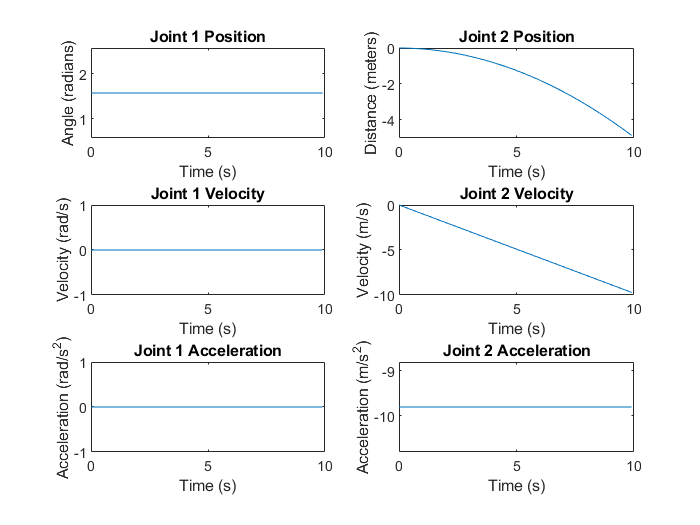

% close all
n=100;
t = 0:0.1:(0.1*(n-1));
q1_0 = pi/2;            % Initial Position assigned to Joint 1
q2_0 = 0;               % Initial Position assigned to Joint 2
dq1_0 = 0;              % Initial Velcocity assigned to Joint 1
dq2_0 = 0;              % Initial Velcocity assigned to Joint 2
U = [0;0];              % Required Input Torque | Force

dt=0.01;
for i = 1:n
     q1p(i)=q1_0;
     q2p(i)=q2_0;
     dq1p(i)=dq1_0;
     dq2p(i)=dq2_0;
     ddq(:,i) = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
     dq1_0=dq1p(i) + double(ddq(1,i)*dt);
     dq2_0=dq2p(i) + double(ddq(2,i)*dt);

     q1_0 = q1p(i) + dq1_0*dt;
     q2_0 = q2p(i) + dq2_0*dt;

end
ddq1 = ddq(1,:);
ddq2 = ddq(2,:);

figure
subplot(3,2,1)
plot(t,q1p)
title('Joint 1 Position')
ylabel('Angle (radians)'); xlabel('Time (s)')
subplot(3,2,3)
plot(t,dq1p)
title('Joint 1 Velocity')
ylabel('Velocity (rad/s)'); xlabel('Time (s)')
subplot(3,2,5)
plot(t,ddq1)
title('Joint 1 Acceleration')
ylabel('Acceleration (rad/s^2)'); xlabel('Time (s)')
subplot(3,2,2)
plot(t,q2p)
title('Joint 2 Position')
ylabel('Distance (meters)'); xlabel('Time (s)')
subplot(3,2,4)
plot(t,dq2p)
title('Joint 2 Velocity')
ylabel('Velocity (m/s)'); xlabel('Time (s)')
subplot(3,2,6)
plot(t,ddq2)
title('Joint 2 Acceleration')
ylabel('Acceleration (m/s^2)'); xlabel('Time (s)')

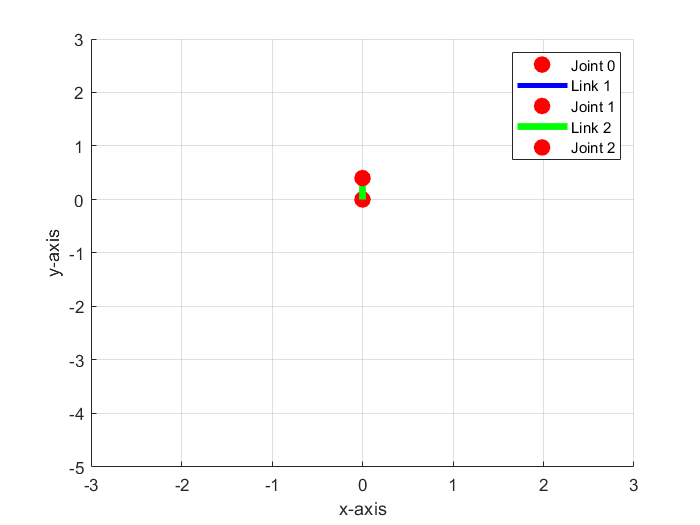

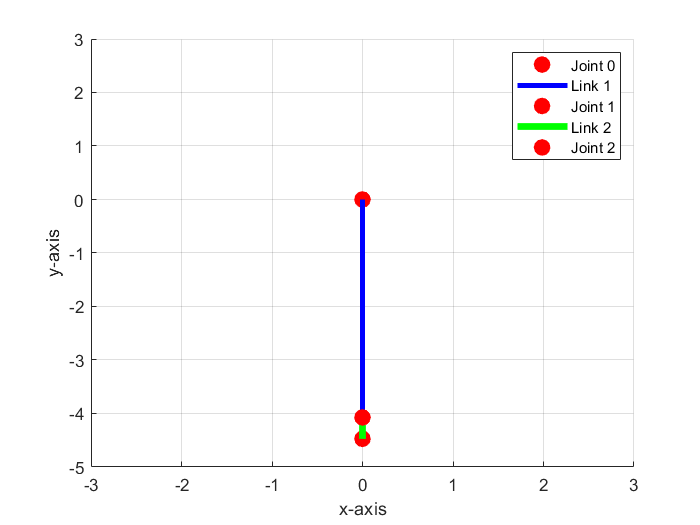


% Robot Simulation
% close all
figure
for i = 1:5:length(q1p)
    clf
    robot([0.2],[q1p(i),q2p(i)])
    pause(0.001)
end

## Testing the Robot Model with Forward Dynamics

i.e         Input $\to$ Torque | Force                       Output  →  Trajectory $\left(\left(\phi^¨ \;,\ddot{S} \right),\left(\phi^˙ ,\dot{S} \right),\left(\phi ,S\right)\right)$           

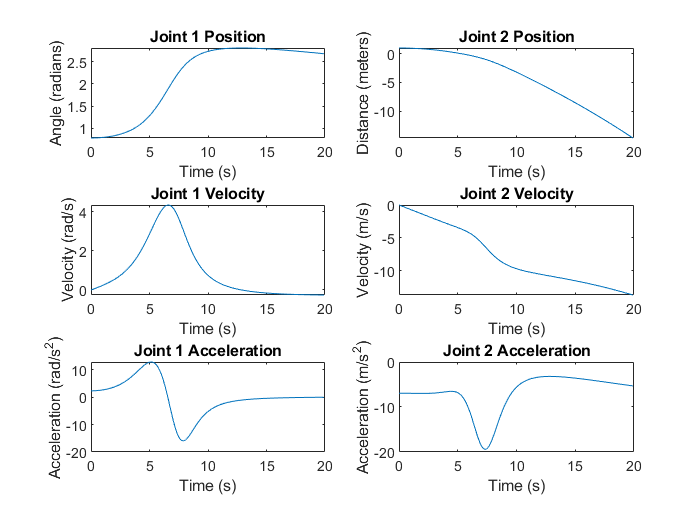

% clear all
% close all
n=200;
t = 0:0.1:(0.1*(n-1));
q1_0 = deg2rad(45);            % Initial Position assigned to Joint 1
q2_0 = 1;               % Initial Position assigned to Joint 2
dq1_0 = 0;              % Initial Velcocity assigned to Joint 1
dq2_0 = 0;              % Initial Velcocity assigned to Joint 2
U = [30;0];              % Required Input Torque | Force

dt=0.01;
for i = 1:n
     q1p(i)=q1_0;
     q2p(i)=q2_0;
     dq1p(i)=dq1_0;
     dq2p(i)=dq2_0;
     ddq(:,i) = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
     dq1_0=dq1p(i) + double(ddq(1,i)*dt);
     dq2_0=dq2p(i) + double(ddq(2,i)*dt);

     q1_0 = q1p(i) + dq1_0*dt;
     q2_0 = q2p(i) + dq2_0*dt;
end
ddq1 = ddq(1,:);
ddq2 = ddq(2,:);

figure
subplot(3,2,1)
plot(t,q1p)
title('Joint 1 Position')
ylabel('Angle (radians)'); xlabel('Time (s)')
subplot(3,2,3)
plot(t,dq1p)
title('Joint 1 Velocity')
ylabel('Velocity (rad/s)'); xlabel('Time (s)')
subplot(3,2,5)
plot(t,ddq1)
title('Joint 1 Acceleration')
ylabel('Acceleration (rad/s^2)'); xlabel('Time (s)')
subplot(3,2,2)
plot(t,q2p)
title('Joint 2 Position')
ylabel('Distance (meters)'); xlabel('Time (s)')
subplot(3,2,4)
plot(t,dq2p)
title('Joint 2 Velocity')
ylabel('Velocity (m/s)'); xlabel('Time (s)')
subplot(3,2,6)
plot(t,ddq2)
title('Joint 2 Acceleration')
ylabel('Acceleration (m/s^2)'); xlabel('Time (s)')

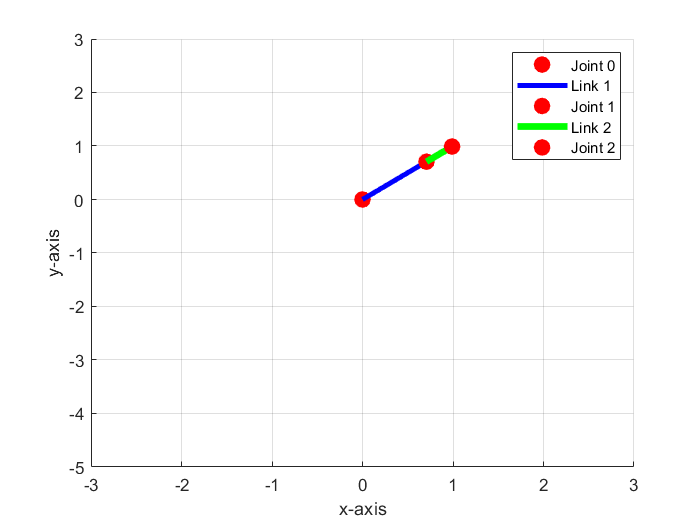

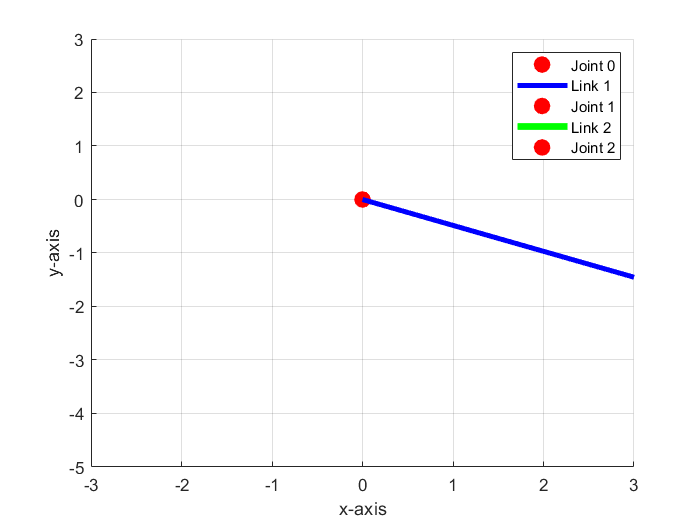


% Robot Simulation
% close all
figure
for i = 1:5:length(q1p)
    clf
    robot([0.2],[q1p(i),q2p(i)])
    pause(0.001)
end

## Testing the Robot Model with input Functions

% clear all
% close all
n=200;
t = 0:0.1:(0.1*(n-1));
q1_0 = deg2rad(0);             % Initial Position assigned to Joint 1
q2_0 = 1;                      % Initial Position assigned to Joint 2
dq1_0 = 0                      % Initial Velcocity assigned to Joint 1

dq1_0 = 0

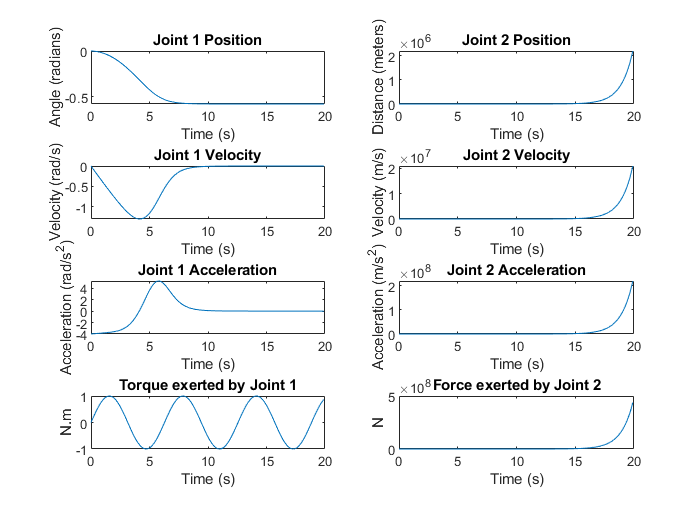

dq2_0 = 0;                     % Initial Velcocity assigned to Joint 2
U = [sin(t);exp(t)];                   % Required Input Torque | Force

dt=0.01;
for i = 1:n
     q1p(i)=q1_0;
     q2p(i)=q2_0;
     dq1p(i)=dq1_0;
     dq2p(i)=dq2_0;
     ddq(:,i) = inv(D(q1_0, q2_0))*(U(:,i)-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
     dq1_0=dq1p(i) + double(ddq(1,i)*dt);
     dq2_0=dq2p(i) + double(ddq(2,i)*dt);

     q1_0 = q1p(i) + dq1_0*dt;
     q2_0 = q2p(i) + dq2_0*dt;
end
ddq1 = ddq(1,:);
ddq2 = ddq(2,:);

figure
subplot(4,2,1)
plot(t,q1p)
title('Joint 1 Position')
ylabel('Angle (radians)'); xlabel('Time (s)')
subplot(4,2,3)
plot(t,dq1p)
title('Joint 1 Velocity')
ylabel('Velocity (rad/s)'); xlabel('Time (s)')
subplot(4,2,5)
plot(t,ddq1)
title('Joint 1 Acceleration')
ylabel('Acceleration (rad/s^2)'); xlabel('Time (s)')
subplot(4,2,7)
plot(t,U(1,:))
title('Torque exerted by Joint 1')
ylabel('N.m'); xlabel('Time (s)')
subplot(4,2,2)
plot(t,q2p)
title('Joint 2 Position')
ylabel('Distance (meters)'); xlabel('Time (s)')
subplot(4,2,4)
plot(t,dq2p)
title('Joint 2 Velocity')
ylabel('Velocity (m/s)'); xlabel('Time (s)')
subplot(4,2,6)
plot(t,ddq2)
title('Joint 2 Acceleration')
ylabel('Acceleration (m/s^2)'); xlabel('Time (s)')
subplot(4,2,8)
plot(t,U(2,:))
title('Force exerted by Joint 2')
ylabel('N'); xlabel('Time (s)')

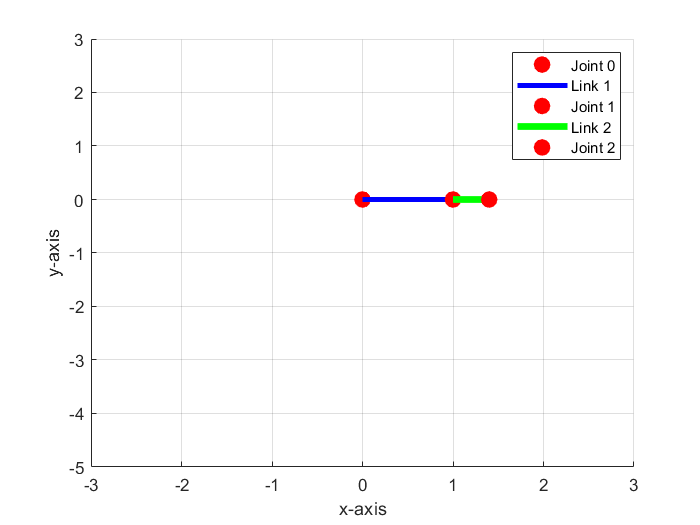

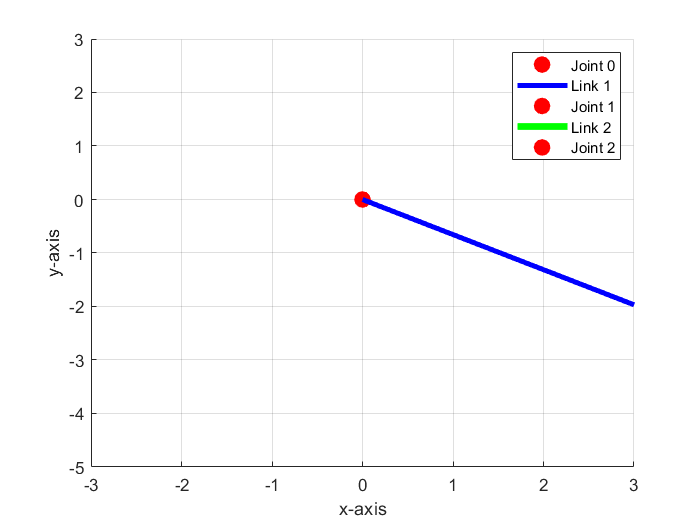


% Robot Simulation
% close all
figure
for i = 1:5:length(q1p)
    clf
    robot([0.2],[q1p(i),q2p(i)])
    pause(0.001)
end